exercise 1

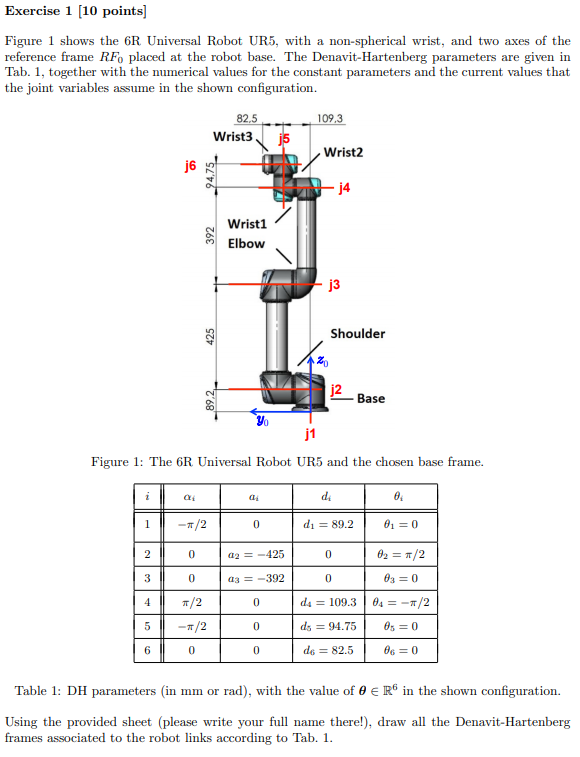

clear all, close all, clc
syms A B C D q1 q2
Njoints=3;
q=sym('q',[Njoints,1]);
L_=3

L_ = 3

d1_=1;
d2_=1;
syms alpha beta gamma L

a1=A

$$a1 = A$$

a2=6

a2 = 6

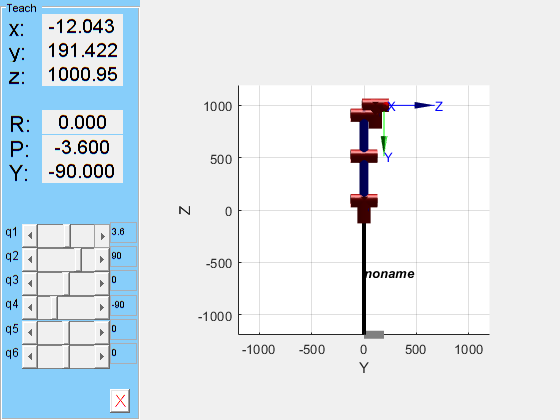

dhTable=[pi/2,0,0,q(1);
         -pi/2,0,q(2),0;
         0,L,0,q(3)
         ];
links = [
    Revolute('alpha', -pi/2,'a', 0,'d', 89.2)
%     Prismatic('qlim', [0 5],'alpha',-pi/2,'theta',0);
    Revolute('alpha',  0,      'a', -425,'d', 0);
    Revolute('alpha',  0,      'a', -392,'d', 0);
     Revolute('alpha',  pi/2,   'a', 0,'d', 109.3);
     Revolute('alpha', -pi/2,   'a', 0,'d', 94.75);
     Revolute('alpha',  0,      'a', 0,'d', 82.5);

    ];
c600 = SerialLink(links);
c600.teach([0,pi/2,0,-pi/2,0,0],'view','y')

Exercise 3

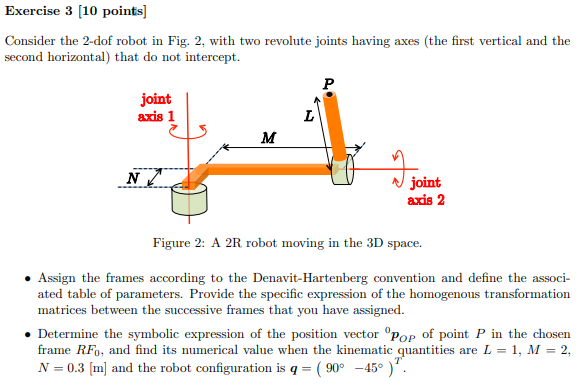

clear all, close all, clc
syms A B C D q1 q2
Njoints=2;
q=sym('q',[Njoints,1]);
L_=3
d1_=1;
d2_=1;
syms alpha beta gamma L N M

a1=A
a2=6
dhTable=[pi/2,N,0,q(1);
         0,L,M,q(2);
         ];
links = [
    Revolute('alpha', pi/2,'a', 5,'d', 0)
%     Prismatic('qlim', [0 5],'alpha',-pi/2,'theta',0);
    Revolute('alpha',  0,      'a', 5,'d', 5);
%     Revolute('alpha',  0,      'a', -392,'d', 0);
%      Revolute('alpha',  pi/2,   'a', 0,'d', 109.3);
%      Revolute('alpha', -pi/2,   'a', 0,'d', 94.75);
%      Revolute('alpha',  0,      'a', 0,'d', 82.5);

    ];
c600 = SerialLink(links);
c600.teach([0,0],'view','x')
[TTotal TPartial,RTotal,RPartial,PTotal, PPartial]= getTransformationMatrix(dhTable, 'alpha')
param=[L; N ;M]
param_=[1 0.3 2]'
o_P_op=simplify(subs(PTotal,param,param_))
q_=[pi/2,-pi/4]'
digits(5)
o_P_op=vpa(simplify(subs(o_P_op,q,q_)))

Exercice 4

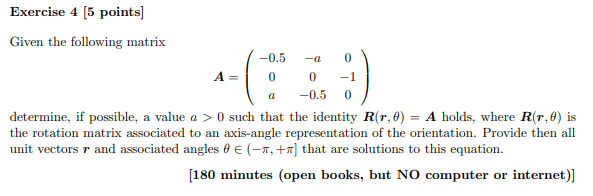

syms a real
r=sym('r',[3,1]);
angle=sym('theta');
A_=[-0.5,-a,0;
    0,0,-1;
    a,-0.5,0];
A_R_B=getRotAroundVector(r,angle)
 R_r_theta_=solve(A_R_B==A_)
 digits(5)
 vpa(R_r_theta_.a)
 vpa(R_r_theta_.theta*180/pi)
 vpa(R_r_theta_.r1)

 vpa(R_r_theta_.r2)
 A_=subs(A_,a,R_r_theta_.a(1))
  R_r_theta_=solve(A_R_B==A_)
digits(5)
 vpa(R_r_theta_.theta*180/pi)
 vpa(R_r_theta_.r1)

 vpa(R_r_theta_.r2)